# 3. Building Classification Models

## Supervised Learning

Course Example: Heart Disease

% Load the example data
load('heartdisease.mat')
% Is it necessary to apply a classification model to the data?
% Pre-evaluation of the data
[g,c]=kmeans(zscore(heartdataNum{:,1:11}),2,'Replicates',5);
counts=crosstab(g,heartdataNum.HeartDisease)

counts =     67   171
   124    65


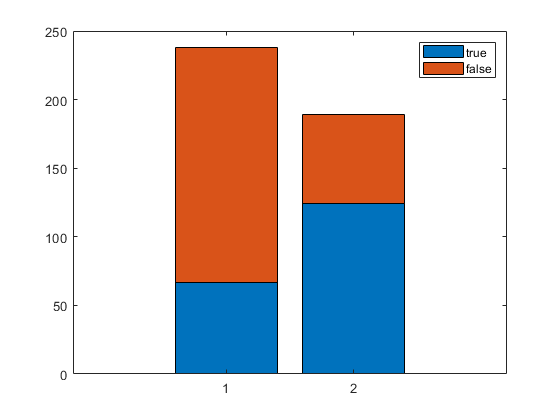

figure
bar(counts,'stacked')
legend([{'true'},{'false'}])

### Training and Validation

% Divide the heart disease into training(80%) and validation(20%) sets
rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2)

part = 홀드아웃 교차 검증 분할
   NumObservations: 427
       NumTestSets: 1
         TrainSize: 342
          TestSize: 85

tridx=training(part);
tdata=heartdataNum(tridx,:)

tdata = 342×12 table
      Age      Cholesterol    ExerciseDuration     METs     RestingHeartRate    RestingSystolic    RestingDiastolic    MaxHeartRate    PeakExSystolic    PeakExDiastolic    InducedSTDep    HeartDisease
    _______    ___________    ________________    ______    ________________    _______________    ________________    ____________    ______________    _______________    ____________    ____________

    0.70833      0.37151          0.48649         0.6875        0.25316             0.49074            0.58333           0.60902          0.67949            0.61538           0.41071         false    
    0.79167      0.51955          0.43243         0.6875         0.3038             0.62963            0.66667           0.29323          0.48718            0.61538           0.26786         true     
    0.16667      0.41899          0.62162         0.9375        0.55696             0.35185            0.46667           0.88722          0.71154            0.40385          

vdata=heartdataNum(~tridx,:)

vdata = 85×12 table
      Age      Cholesterol    ExerciseDuration     METs     RestingHeartRate    RestingSystolic    RestingDiastolic    MaxHeartRate    PeakExSystolic    PeakExDiastolic    InducedSTDep    HeartDisease
    _______    ___________    ________________    ______    ________________    _______________    ________________    ____________    ______________    _______________    ____________    ____________

    0.79167      0.36034          0.37838            0.5        0.48101             0.25926                0.5           0.45113          0.35897            0.51923           0.46429         true     
    0.70833      0.43017          0.35135         0.4375        0.44304             0.35185            0.91667           0.58647          0.23077            0.42308              0.25         true     
    0.58333      0.25698          0.36216         0.4375        0.58228             0.44444            0.66667           0.59398          0.61538            0.47115          0

tdataAll=heartdataAll(tridx,:);
vdataAll=heartdataAll(~tridx,:);


### 1. Nearest Neighbor Classification(1/2)

The most straightforward way of classification without any assumptions about the underlying distribution of the data

m = fitcknn(tdata,'HeartDisease');

m =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


% Why use tdata, not tdataAll? because k-NN does not accept mixed predictors(numeric+categorical).

### Evaluating Classifications

m = fitcknn(tdata,'HeartDisease')

m =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


% Measure loss


errKNN_train = 0

errKNN_train=resubLoss(m) % Measure loss with the training data

errKNN_test = 0.3413

errKNN_test=loss(m,vdata) % Measure loss with the test(validation) data

% Visualize prediction accuracy
HDpred=predict(m,vdata)

HDpred = 85×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 


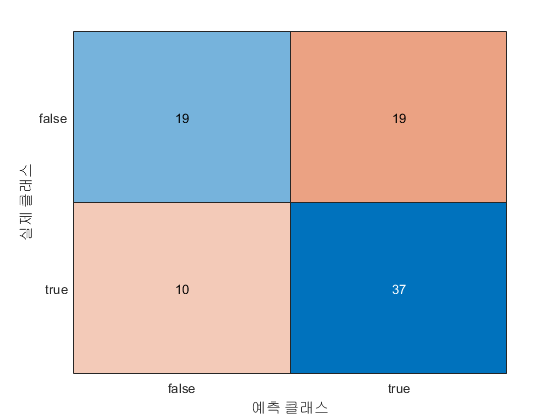

HDtrue=vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)

### 1. Nearest Neighbor Classification(2/2)

% Check overfitting and Update model 1
m.NumNeighbors=5; % m = fitcknn(tdata,'HeartDisease',"NumNeighbors",5)
errKNN_train=resubLoss(m)

errKNN_train = 0.2222

errKNN_test=loss(m,vdata)

errKNN_test = 0.2471

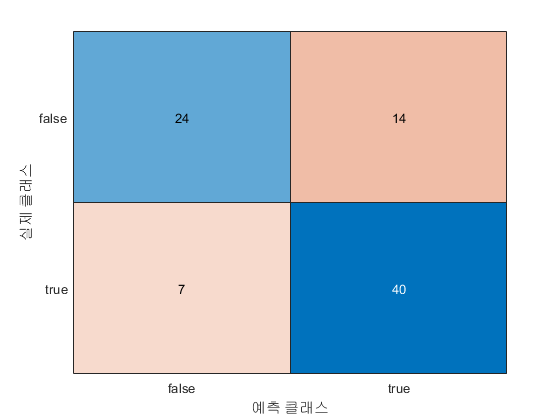

HDpred=predict(m,vdata);
HDtrue=vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred) 

 
 

% Update model 2
m.DistanceWeight='squaredinverse'

m =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


errKNN_train=resubLoss(m)

errKNN_train = 0

errKNN_test=loss(m,vdata)

errKNN_test = 0.2471

### 2. Decision Tree Classification

A decision tree model make a categorical response prediction by following a sequence of binary decisions based on predictor variable value. It does not assume any underlying distributions of the data like k-NN.

A decision tree model is robust to noise data.

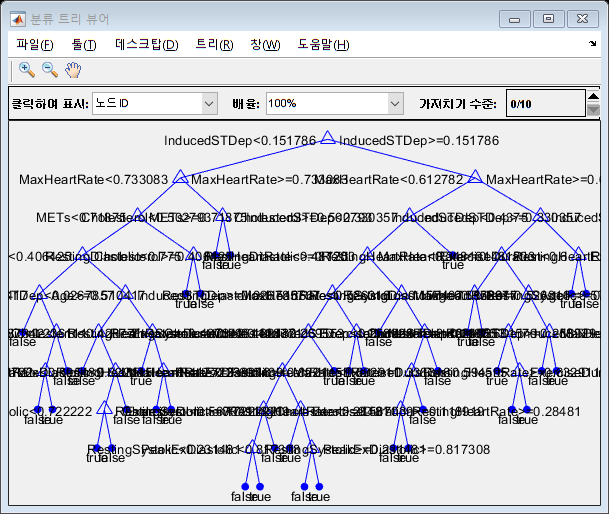

% Fit and evaluate a decision tree model with default settings
m=fitctree(tdata,'HeartDisease');
view(m,'Mode','graph')


errDT_train=resubLoss(m)

errDT_train = 0.0789

errDT_test=loss(m,vdata)

errDT_test = 0.2824

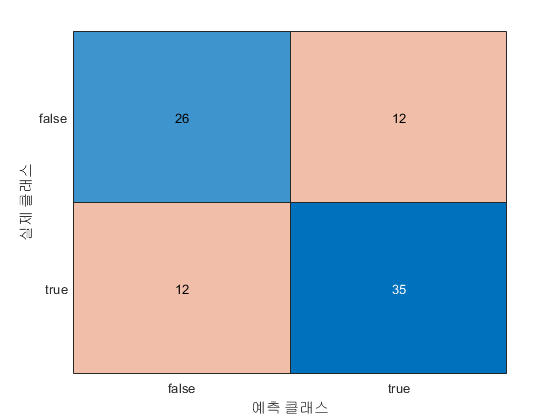

HDpred=predict(m,vdata);
HDtrue=vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred) 


% Check overfitting and update model with 'prune' function
m=prune(m,'Level',3)

m =   ClassificationTree
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


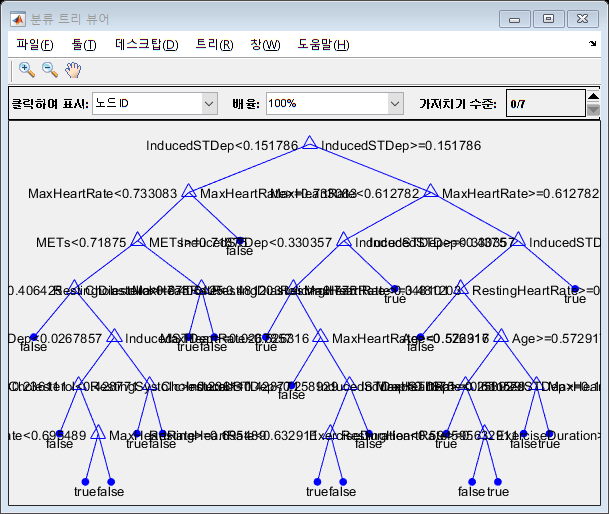

view(m,'Mode','graph')

errPrunedDT_train=resubLoss(m)

errPrunedDT_train = 0.1404

errPrunedDT_test=loss(m,vdata)

errPrunedDT_test = 0.2000



% Unlike k-NN, a decision tree model accepts mixed data(numeric + categorical)
m=fitctree(tdataAll,'HeartDisease')

m =   ClassificationTree
           PredictorNames: {1×21 cell}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: [12 13 14 15 16 17 18 19 20 21]
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


errDT_train=resubLoss(m)

errDT_train = 0.0556

errDT_test=loss(m,vdataAll)

errDT_test = 0.2353


m=prune(m,'Level',3)

m =   ClassificationTree
           PredictorNames: {1×21 cell}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: [12 13 14 15 16 17 18 19 20 21]
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


errPrunedDT_train=resubLoss(m)

errPrunedDT_train = 0.1082

errPrunedDT_test=loss(m,vdataAll)

errPrunedDT_test = 0.2118

### 3. Naive Bayes Classification

A Naive Bayes model uses Bayes's rule of conditional probability to estimate the probability of a given observation being in each response class. Accordingly, it assumes an underlying distribution of the data. (Note: Each predictor variable should be independent, If not, use a 'Discriminant Analysis')

m=fitcnb(tdata,'HeartDisease')

m =   ClassificationNaiveBayes
            PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
              ResponseName: 'HeartDisease'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 342
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×11 cell}


  Properties, Methods


errNB_train=resubLoss(m)

errNB_train = 0.2982

errNB_test=loss(m,vdata)

errNB_test = 0.2000



% Use kernel smoothing instead of normal distributions
% Kernel smoothing only works for numeric predictor variables
m=fitcnb(tdata,'HeartDisease',"DistributionNames","kernel")

m =   ClassificationNaiveBayes
            PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
              ResponseName: 'HeartDisease'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 342
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×11 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2

errNB_train=resubLoss(m)

errNB_train = 0.2602

errNB_test=loss(m,vdataAll)

errNB_test = 0.1765


% Use a mix of numeric and categorical predictors and use kernel smoothing for all numerical predictors
m=fitcnb(tdataAll,'HeartDisease');
errNB_train=resubLoss(m)

errNB_train = 0.2047

errNB_test=loss(m,vdataAll)

errNB_test = 0.1177


dists=[repmat({'kernel'},1,11),repmat({'mvmn'},1,10)]

dists = 1×21 cell 배열
    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}


m=fitcnb(tdataAll,'HeartDisease',"DistributionNames",dists);
errNB_train=resubLoss(m)

errNB_train = 0.1959

errNB_test=loss(m,vdataAll)

errNB_test = 0.1412